# Figures of average acoustic features per bat

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'MicAudioGood','CallType','OnSetOffsetSample',...
    'TmicAll','BatID', 'Duration','RMS_mean','Sal_mean',...
    'F0_mean','F0_cv','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean', 'AmpPeriodF','AmpPeriodP')
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
DurationElmt = diff(OnSetOffsetSample,1,2)/192000*1000;% in ms
fprintf(1,'In total, there are %d Vocal elements, %d are also of good microphone quality\n', length(MicAudioGood01), sum(MicAudioGood01))

In total, there are 36227 Vocal elements, 28091 are also of good microphone quality


Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Female';
    end

end
USexDeaf = {'Kanamycin Male' 'Saline Male' 'Kanamycin Female' 'Saline Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

Construct the table of PAF for statistical purposes

Construct the table of PAF for statistical purposes

Tbl =  table(BatID(MicAudioGood01),...
    CallType(MicAudioGood01),...
    Sex(MicAudioGood01),...
    Deaf(MicAudioGood01),...
    DurationElmt(MicAudioGood01),...
    RMS_mean(MicAudioGood01),...
    Sal_mean(MicAudioGood01),...
    F0_mean(MicAudioGood01)/1000,...
    F0_cv(MicAudioGood01),...
    Spect_mean(MicAudioGood01)/10^3,...
    Spect_std(MicAudioGood01)/10^3,...
    Spect_kurt(MicAudioGood01),...
    Spect_skew(MicAudioGood01),...
    Spect_ent(MicAudioGood01),...
    Time_mean(MicAudioGood01),...
    Time_std(MicAudioGood01),...
    Time_kurt(MicAudioGood01),...
    Time_skew(MicAudioGood01),...
    Time_ent(MicAudioGood01),...
    Q1_mean(MicAudioGood01)/10^3,...
    Q2_mean(MicAudioGood01)/10^3,...
    Q3_mean(MicAudioGood01)/10^3,...
    SpectMic_mean(MicAudioGood01)/10^3,...
    SpectMic_std(MicAudioGood01)/10^3,...
    SpectMic_kurt(MicAudioGood01),...
    SpectMic_skew(MicAudioGood01),...
    SpectMic_ent(MicAudioGood01),...
    Q1Mic_mean(MicAudioGood01)/10^3,...
    Q2Mic_mean(MicAudioGood01)/10^3,...
    Q3Mic_mean(MicAudioGood01)/10^3,...
    AmpPeriodF(MicAudioGood01),...
    AmpPeriodP(MicAudioGood01),...
    'VariableNames', {'BatID', 'CT','Sex','HorD',...
    'Duration (ms)','RMS mean','Saliency (AU)','Fund (kHz)','Fund CV','S mean (kHz)','S std (kHz)','S kurt (Hz)','S skew (Hz)','S ent',...
    'T mean (ms)','T std (ms)','T kurt (ms)','T skew (ms)','T ent','1st SQ (kHz)','2nd SQ (kHz)','3rd SQ (kHz)','Mic S mean (kHz)','Mic S std (kHz)',...
    'Mic S kurt (Hz)','Mic S skew (Hz)','Mic S ent','Mic 1st SQ (kHz)','Mic 2nd SQ (kHz)','Mic 3rd SQ (kHz)','Amp P F (Hz)','Amp P P'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});

Go through all acoustic categories and calculate and plot the average values of features for all individuals

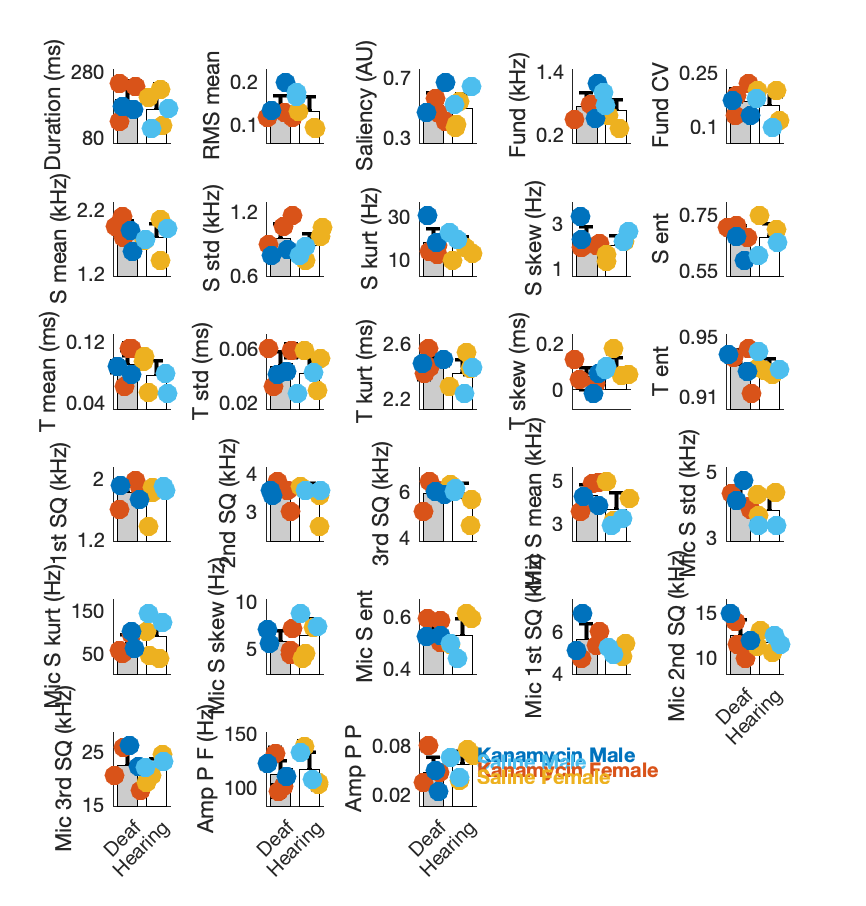

*********************     Calculations on Duration (ms)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lmeR     4     3.9747e+05     3.975e+05    -1.9873e+05                                 
    lme      6     3.9747e+05    3.9752e+05    -1.9873e+05    0.91957    2          0.63142


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat      deltaDF    pValue 
    lme2     5     3.9747e+05    3.9751e+05    -1.9873e+05                                  
    lme      6     3.9747e+05    3.9752e+05    -1.9873e+05    0.033172    1          0.85548


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    3.9747e+05    3.9752e+05    -1.9873e+05      3.9746e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF       pValue        Lower      Upper 
    {'(Intercept)' }         179.67     23.656     7.5951    28087    3.1723e-14      133.3    226.03
    {'Sex_M'       }        -42.721     37.308    -1.1451    28087       0.25218    -115.85    30.405
    {'HorD_D'      }         21.136     33.499    0.63094    28087       0.52808    -44.523    86.794
    {'Sex_M:HorD_D'}         9.6398     5

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lmeR2       3     3.9747e+05    3.9749e+05    -1.9873e+05                                 
    lmefull2    4     3.9747e+05     3.975e+05    -1.9873e+05    0.74299    1          0.38871


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC          LogLikelihood    Deviance  
    3.9747e+05    3.975e+05    -1.9873e+05      3.9746e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat      DF       pValue        Lower      Upper 
    {'(Intercept)'}        162.53      20.121     8.0774    28089    6.8774e-16     123.09    201.97
    {'HorD_D'     }         25.04      28.503    0.87851    28089       0.37967    -30.826    80.906

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type  

Pvalue_matrix_MannU = 	1.0e+-7 *

    0.6463
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


*********************     Calculations on RMS mean   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -59672    -59639    29840                                 
    lme      6     -59669    -59619    29840     1.117     2          0.57207


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue 
    lme2     5     -59670    -59629    29840                                  
    lme      6     -59669    -59619    29840     0.76156    1          0.38284


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -59669    -59619    29840            -59681  

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat      DF       pValue        Lower       Upper   
    {'(Intercept)' }          0.10318    0.010314     10.004    28087     1.595e-23    0.082968      0.1234
    {'Sex_M'       }         0.065843    0.016289     4.0422    28087    5.3088e-05    0.033916    0.097769
    {'HorD_D'      }         0.015276    0.014595     1.0467    28087       0.29524    -0.01333    0.043882
    {'Sex_M:HorD_D'}        -0.020521

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue 
    lmeR2       3     -59662    -59638    29834                                  
    lmefull2    4     -59661    -59628    29834     0.11498    1          0.73455


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -59661    -59628    29834            -59669  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF       pValue        Lower        Upper   
    {'(Intercept)'}          0.12953    0.014742     8.7861    28089    1.6345e-18      0.10063     0.15842
    {'HorD_D'     }        0.0070914    0.020854    0.34005    28089       0.73382    -0.033784    0.047967

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Typ

Pvalue_matrix_MannU = 	1.0e+-3 *

    0.0001
    0.5103
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


*********************     Calculations on Saliency (AU)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     4     -4574.3    -4541.4    2291.1                                 
    lme      6     -4570.9    -4521.6    2291.4    0.60378    2          0.73942


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lme2     5     -4572.5    -4531.4    2291.2                                 
    lme      6     -4570.9    -4521.6    2291.4    0.40457    1          0.52474


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           27004
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -4570.9    -4521.6    2291.4           -4582.9 

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat      DF       pValue       Lower        Upper  
    {'(Intercept)' }          0.42834      0.0423     10.126    27000    4.666e-24      0.34543    0.51125
    {'Sex_M'       }          0.14795    0.066848     2.2132    27000     0.026891     0.016924    0.27897
    {'HorD_D'      }         0.045534    0.059839    0.76094    27000       0.4467    -0.071754    0.16282
    {'Sex_M:HorD_D'}        -0.060779

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue
    lmeR2       3     -4571.7    -4547.1    2288.8                                
    lmefull2    4     -4569.8      -4537    2288.9    0.12573    1          0.7229


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           27004
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC      LogLikelihood    Deviance
    -4569.8    -4537    2288.9           -4577.8 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue        Lower        Upper  
    {'(Intercept)'}         0.48754      0.0422     11.553    27002    8.4003e-31      0.40483    0.57026
    {'HorD_D'     }        0.021232    0.059694    0.35568    27002       0.72208    -0.095772    0.13824

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type     

Pvalue_matrix_MannU = 	1.0e+-3 *

    0.0001
    0.5103
    0.0000
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


*********************     Calculations on Fund (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR     4     40042    40074    -20017                                 
    lme      6     40045    40094    -20016    0.97804    2          0.61323


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lme2     5     40043    40084    -20017                                
    lme      6     40045    40094    -20016    0.52338    1          0.4694


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           24593
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    40045    40094    -20016           40033   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF       pValue        Lower        Upper  
    {'(Intercept)' }         0.50986    0.11115     4.5871    24589    4.5163e-06        0.292    0.72773
    {'Sex_M'       }         0.35322    0.17566     2.0109    24589      0.044352    0.0089217    0.69751
    {'HorD_D'      }         0.15815    0.15724     1.0058    24589       0.31451     -0.15004    0.46635
    {'Sex_M:HorD_D'}        -0.18219    0.24852  

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR2       3     40043    40068    -20019                                 
    lmefull2    4     40045    40077    -20018    0.32224    1          0.57026


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           24593
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    40045    40077    -20018           40037   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF       pValue        Lower       Upper  
    {'(Intercept)'}         0.65124    0.10539     6.1793    24591    6.5412e-10     0.44467    0.85781
    {'HorD_D'     }        0.085307    0.14908    0.57221    24591       0.56719    -0.20691    0.37752

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type           Esti

Pvalue_matrix_MannU = 	1.0e+-3 *

    0.0001
    0.5103
    0.0000
    0.0007
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


*********************     Calculations on Fund CV   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     4     2581.2    2613.7    -1286.6                                 
    lme      6       2585    2633.6    -1286.5    0.27528    2          0.87141


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC     BIC       LogLik     LRStat      deltaDF    pValue 
    lme2     5     2583    2623.5    -1286.5                                  
    lme      6     2585    2633.6    -1286.5    0.027125    1          0.86918


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           24592
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    2585    2633.6    -1286.5          2573    

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat      DF       pValue       Lower        Upper   
    {'(Intercept)' }          0.16984    0.020893     8.1291    24588    4.526e-16      0.12889      0.2108
    {'Sex_M'       }        -0.035465    0.032931     -1.077    24588       0.2815     -0.10001    0.029081
    {'HorD_D'      }        0.0084053    0.029601    0.28395    24588      0.77645    -0.049615    0.066425
    {'Sex_M:HorD_D'}        0.0076962    

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR2       3     2580.9    2605.2    -1287.4                                 
    lmefull2    4     2582.7    2615.1    -1287.3    0.21035    1          0.64649


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           24592
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2582.7    2615.1    -1287.3          2574.7  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue        Lower        Upper   
    {'(Intercept)'}          0.1556    0.017586     8.8479    24590    9.5028e-19      0.12113     0.19007
    {'HorD_D'     }        0.011495    0.024921    0.46126    24590       0.64461    -0.037352    0.060342

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type  

Pvalue_matrix_MannU = 	1.0e+-3 *

    0.0001
    0.5103
    0.0000
    0.0007
    0.0000
       NaN
       NaN
       NaN
       NaN
       NaN


*********************     Calculations on S mean (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     4     41064    41096    -20528                                
    lme      6     41065    41115    -20527    2.1479    2          0.34166


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme2     5     41065    41106    -20528                                
    lme      6     41065    41115    -20527    1.717     1          0.19008


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    41065    41115    -20527           41053   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF       pValue        Lower        Upper  
    {'(Intercept)' }          1.7122    0.10682     16.028    28087    1.4701e-57       1.5028     1.9215
    {'Sex_M'       }        0.098118    0.16884    0.58114    28087       0.56115     -0.23281    0.42905
    {'HorD_D'      }         0.21542     0.1511     1.4257    28087       0.15397    -0.080745    0.51159
    {'Sex_M:HorD_D'}        -0.32695    0.23886  

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR2       3     41062    41086    -20528                                 
    lmefull2    4     41063    41096    -20528    0.42072    1          0.51658


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    41063    41096    -20528           41055   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue        Lower       Upper 
    {'(Intercept)'}         1.7514     0.091275     19.188    28089    1.5392e-81      1.5725    1.9303
    {'HorD_D'     }        0.08463      0.12911    0.65547    28089       0.51217    -0.16844    0.3377

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type           Esti

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
       NaN
       NaN
       NaN
       NaN


*********************     Calculations on S std (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     4     874.81    907.78     -433.4                                
    lme      6     876.73    926.19    -432.36    2.0786    2          0.35371


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue
    lme2     5     875.85    917.06    -432.92                               
    lme      6     876.73    926.19    -432.36    1.1168    1          0.2906


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    876.73    926.19    -432.36          864.73  

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat       DF       pValue        Lower        Upper   
    {'(Intercept)' }          0.91298    0.055932      16.323    28087    1.2727e-59      0.80335      1.0226
    {'Sex_M'       }        -0.085193    0.088407    -0.96365    28087       0.33523     -0.25847    0.088088
    {'HorD_D'      }          0.11948    0.079114      1.5102    28087         0.131    -0.035587     0.27455
    {'Sex_M:HorD_D'}         

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR2       3     876.78    901.51    -435.39                                 
    lmefull2    4     878.14    911.11    -435.07    0.63702    1          0.42479


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    878.14    911.11    -435.07          870.14  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue        Lower        Upper  
    {'(Intercept)'}          0.8789    0.056775      15.48    28089    7.8433e-54      0.76762    0.99018
    {'HorD_D'     }        0.065128    0.080304    0.81101    28089       0.41737    -0.092272    0.22253

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type     

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
       NaN
       NaN
       NaN


*********************     Calculations on S kurt (Hz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue 
    lmeR     4     2.5866e+05    2.5869e+05    -1.2933e+05                                
    lme      6     2.5866e+05    2.5871e+05    -1.2933e+05    1.1929    2          0.55076


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lme2     5     2.5866e+05     2.587e+05    -1.2933e+05                                 
    lme      6     2.5866e+05    2.5871e+05    -1.2933e+05    0.18475    1          0.66732


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    2.5866e+05    2.5871e+05    -1.2933e+05      2.5865e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF       pValue        Lower      Upper 
    {'(Intercept)' }         12.46      1.9081     6.5303    28087    6.6757e-11     8.7203      16.2
    {'Sex_M'       }        8.0504      3.0085     2.6759    28087      0.007457     2.1536    13.947
    {'HorD_D'      }        1.4321      2.7023    0.52997    28087       0.59614    -3.8645    6.7288
    {'Sex_M:HorD_D'}        1.8412      4

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue
    lmeR2       3     2.5867e+05    2.5869e+05    -1.2933e+05                                
    lmefull2    4     2.5867e+05     2.587e+05    -1.2933e+05    0.38039    1          0.5374


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC          LogLikelihood    Deviance  
    2.5867e+05    2.587e+05    -1.2933e+05      2.5866e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat      DF       pValue        Lower      Upper 
    {'(Intercept)'}        15.685      2.4687     6.3535    28089    2.1371e-10     10.846    20.524
    {'HorD_D'     }        2.1753       3.494    0.62257    28089       0.53357    -4.6731    9.0237

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type  

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
       NaN
       NaN


*********************     Calculations on S skew (Hz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     4     1.0656e+05    1.0659e+05    -53276                                
    lme      6     1.0656e+05    1.0661e+05    -53274    2.487     2          0.28837


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat      deltaDF    pValue 
    lme2     5     1.0656e+05     1.066e+05    -53274                                  
    lme      6     1.0656e+05    1.0661e+05    -53274    0.021246    1          0.88411


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.0656e+05    1.0661e+05    -53274           1.0655e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF       pValue        Lower       Upper  
    {'(Intercept)' }          1.692     0.18445     9.1732    28087    4.8958e-20      1.3305     2.0536
    {'Sex_M'       }        0.73143     0.29126     2.5113    28087      0.012035     0.16055     1.3023
    {'HorD_D'      }        0.31401     0.26103     1.2029    28087       0.22902    -0.19764    0.82565
    {'Sex_M:HorD_D'}        0

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR2       3     1.0656e+05    1.0659e+05    -53279                                
    lmefull2    4     1.0657e+05     1.066e+05    -53279    1.1197    1          0.28999


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC          LogLikelihood    Deviance  
    1.0657e+05    1.066e+05    -53279           1.0656e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF       pValue        Lower       Upper 
    {'(Intercept)'}         1.9848     0.21973    9.0328    28089    1.7776e-19      1.5541    2.4155
    {'HorD_D'     }        0.33834     0.31089    1.0883    28089       0.27647    -0.27102    0.9477

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Typ

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
       NaN


*********************     Calculations on S ent   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat      deltaDF    pValue 
    lmeR     4     -41984    -41951    20996                                   
    lme      6     -41980    -41930    20996     0.013947    2          0.99305


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat       deltaDF    pValue 
    lme2     5     -41982    -41940    20996                                    
    lme      6     -41980    -41930    20996     0.0031884    1          0.95497


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -41980    -41930    20996            -41992  

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE          tStat       DF       pValue         Lower        Upper    
    {'(Intercept)' }           0.69589    0.018593      37.427    28087    3.2174e-299      0.65944      0.73233
    {'Sex_M'       }         -0.069496    0.029379     -2.3655    28087       0.018012     -0.12708    -0.011912
    {'HorD_D'      }        -0.0030535    0.026304    -0.11609    28087        0.90759     -0.05461     0.048503
    {'Sex_M:HorD_

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC       BIC       LogLik    LRStat       deltaDF    pValue 
    lmeR2       3     -41978    -41954    20992                                    
    lmefull2    4     -41976    -41943    20992     0.0052375    1          0.94231


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -41976    -41943    20992            -41984  

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE          tStat        DF       pValue         Lower       Upper   
    {'(Intercept)'}           0.66808    0.020772       32.162    28089    6.5699e-223     0.62737      0.7088
    {'HorD_D'     }        -0.0021268    0.029384    -0.072379    28089         0.9423    -0.05972    0.055467

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2            

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on T mean (ms)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -33831    -33798    16919                                 
    lme      6     -33828    -33779    16920     1.4046    2          0.49545


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat      deltaDF    pValue 
    lme2     5     -33830    -33789    16920                                   
    lme      6     -33828    -33779    16920     0.046171    1          0.82987


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -33828    -33779    16920            -33840  

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat      DF       pValue        Lower        Upper   
    {'(Intercept)' }          0.08178    0.010672     7.6629    28087    1.8758e-14     0.060862      0.1027
    {'Sex_M'       }        -0.017794    0.016829    -1.0574    28087       0.29036     -0.05078    0.015191
    {'HorD_D'      }         0.012081    0.015114    0.79937    28087       0.42409    -0.017542    0.041705
    {'Sex_M:HorD_D'}        0.005

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR2       3     -33831    -33807    16919                                 
    lmefull2    4     -33830    -33797    16919     1.1818    1          0.27699


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -33830    -33797    16919            -33838  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF       pValue        Lower        Upper   
    {'(Intercept)'}        0.074637    0.0089214    8.3661    28089    6.2259e-17     0.057151    0.092124
    {'HorD_D'     }        0.014161     0.012639    1.1203    28089       0.26258    -0.010613    0.038934

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type  

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on T std (ms)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue 
    lmeR     4     -65631    -65598    32819                                  
    lme      6     -65628    -65578    32820     0.65212    2          0.72176


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat      deltaDF    pValue 
    lme2     5     -65629    -65588    32820                                   
    lme      6     -65628    -65578    32820     0.082625    1          0.77377


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -65628    -65578    32820            -65640  

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE           tStat      DF       pValue        Lower        Upper    
    {'(Intercept)' }         0.046167    0.0061449     7.5131    28087    5.9463e-14     0.034123     0.058211
    {'Sex_M'       }        -0.012207    0.0096905    -1.2597    28087        0.2078    -0.031201    0.0067871
    {'HorD_D'      }        0.0035896    0.0087019     0.4125    28087       0.67997    -0.013467     0.020646
    {'Sex_M:HorD_D'}     

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue 
    lmeR2       3     -65631    -65606    32818                                  
    lmefull2    4     -65629    -65596    32819     0.47064    1          0.49269


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -65629    -65596    32819            -65637  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF       pValue        Lower         Upper   
    {'(Intercept)'}          0.04127    0.0052727      7.827    28089    5.1711e-15      0.030935    0.051604
    {'HorD_D'     }        0.0051865    0.0074691    0.69438    28089       0.48745    -0.0094534    0.019826

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2               

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on T kurt (ms)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lmeR     4     67202    67235    -33597                               
    lme      6     67203    67253    -33596    2.9272    2          0.2314


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme2     5     67202    67243    -33596                                 
    lme      6     67203    67253    -33596    0.77008    1          0.38019


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67203    67253    -33596           67191   

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat      DF       pValue     Lower        Upper  
    {'(Intercept)' }           2.4085    0.046702     51.572    28087          0        2.317        2.5
    {'Sex_M'       }        -0.083541    0.073463    -1.1372    28087    0.25547     -0.22753    0.06045
    {'HorD_D'      }         0.044977    0.066219    0.67921    28087    0.49701    -0.084815    0.17477
    {'Sex_M:HorD_D'}         0.093244     0.10438    

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR2       3     67201    67225    -33597                                
    lmefull2    4     67201    67233    -33596    2.0698    1          0.15025


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67201    67233    -33596           67193   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF       pValue    Lower        Upper  
    {'(Intercept)'}          2.3747    0.038328    61.958    28089         0       2.2996     2.4499
    {'HorD_D'     }        0.082557    0.054396    1.5177    28089    0.1291    -0.024061    0.18918

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type           Estimate    L

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on T skew (ms)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     4     31133    31166    -15562                                
    lme      6     31134    31183    -15561    2.9004    2          0.23452


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme2     5     31132    31173    -15561                                 
    lme      6     31134    31183    -15561    0.29574    1          0.58657


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    31134    31183    -15561           31122   

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE          tStat       DF       pValue        Lower        Upper   
    {'(Intercept)' }           0.10071    0.025044      4.0215    28087    5.7989e-05     0.051625      0.1498
    {'Sex_M'       }        -0.0098258    0.039402    -0.24937    28087       0.80307    -0.087055    0.067404
    {'HorD_D'      }         -0.035553    0.035506     -1.0013    28087       0.31669     -0.10515    0.034041
    {'Sex_M:HorD_D'}         

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR2       3     31131    31156    -15563                                
    lmefull2    4     31131    31164    -15561    2.4373    1          0.11848


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    31131    31164    -15561           31123   

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF       pValue        Lower       Upper    
    {'(Intercept)'}         0.096767    0.020378     4.7486    28089    2.0589e-06    0.056825      0.13671
    {'HorD_D'     }        -0.047901    0.028919    -1.6564    28089      0.097656    -0.10458    0.0087818

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type   

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on T ent   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC            BIC            LogLik    LRStat     deltaDF    pValue 
    lmeR     4     -1.0306e+05    -1.0303e+05    51536                                  
    lme      6     -1.0306e+05    -1.0301e+05    51536     0.23565    2          0.88885


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC            BIC            LogLik    LRStat     deltaDF    pValue
    lme2     5     -1.0306e+05    -1.0302e+05    51536                                 
    lme      6     -1.0306e+05    -1.0301e+05    51536     0.20755    1          0.6487


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC            BIC            LogLikelihood    Deviance   
    -1.0306e+05    -1.0301e+05    51536            -1.0307e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE           tStat       DF       pValue     Lower         Upper   
    {'(Intercept)' }           0.92691     0.004689      197.68    28087          0       0.91772     0.93611
    {'Sex_M'       }         0.0071011    0.0074053     0.95893    28087     0.3376    -0.0074135    0.021616
    {'HorD_D'      }         0.0027928    0.0066354      0.4209    28087    0.67383     -0.010213    0.015799
   

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC            BIC            LogLik    LRStat      deltaDF    pValue 
    lmeR2       3     -1.0307e+05    -1.0304e+05    51536                                   
    lmefull2    4     -1.0306e+05    -1.0303e+05    51536     0.025988    1          0.87193


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC            BIC            LogLikelihood    Deviance   
    -1.0306e+05    -1.0303e+05    51536            -1.0307e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE           tStat     DF       pValue     Lower         Upper   
    {'(Intercept)'}           0.92976    0.0038099    244.04    28089          0       0.92229     0.93723
    {'HorD_D'     }        0.00086979    0.0053925    0.1613    28089    0.87186    -0.0096998    0.011439

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Nam

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on 1st SQ (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     4     7110.4    7143.4    -3551.2                                 
    lme      6     7113.5      7163    -3550.7    0.89866    2          0.63805


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lme2     5     7112.2    7153.4    -3551.1                                 
    lme      6     7113.5      7163    -3550.7    0.67978    1          0.40966


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28088
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC     LogLikelihood    Deviance
    7113.5    7163    -3550.7          7101.5  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF       pValue        Lower        Upper  
    {'(Intercept)' }          1.6817    0.090793     18.522    28084    3.9024e-76       1.5037     1.8596
    {'Sex_M'       }         0.18162     0.14353     1.2653    28084       0.20576    -0.099713    0.46295
    {'HorD_D'      }         0.11652     0.12841    0.90741    28084        0.3642     -0.13517    0.36821
    {'Sex_M:HorD_D'}        -0.17027     0.20

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR2       3     7109.2    7133.9    -3551.6                                 
    lmefull2    4       7111      7144    -3551.5    0.20197    1          0.65314


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28088
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC     BIC     LogLikelihood    Deviance
    7111    7144    -3551.5          7103    

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue         Lower       Upper  
    {'(Intercept)'}          1.7543    0.075764     23.155    28086    1.6223e-117      1.6058     1.9028
    {'HorD_D'     }        0.048401     0.10716    0.45168    28086        0.65151    -0.16163    0.25843

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type           Es

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on 2nd SQ (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR     4     48525    48558    -24258                                 
    lme      6     48528    48578    -24258    0.91347    2          0.63335


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme2     5     48527    48568    -24258                                 
    lme      6     48528    48578    -24258    0.62074    1          0.43077


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28088
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    48528    48578    -24258           48516   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat       DF       pValue        Lower       Upper  
    {'(Intercept)' }          3.2146    0.17527      18.341    28084    1.0647e-74      2.8711     3.5581
    {'Sex_M'       }         0.33699    0.27707      1.2163    28084       0.22389    -0.20608    0.88007
    {'HorD_D'      }         0.23341    0.24789     0.94158    28084       0.34642    -0.25247    0.71929
    {'Sex_M:HorD_D'}        -0.31362    0.39191  

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lmeR2       3     48524    48548    -24259                                
    lmefull2    4     48525    48558    -24259    0.27139    1          0.6024


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28088
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    48525    48558    -24259           48517   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF       pValue         Lower       Upper  
    {'(Intercept)'}         3.3494     0.14549     23.022    28086    3.3482e-116      3.0643     3.6346
    {'HorD_D'     }        0.10793     0.20578    0.52449    28086        0.59994    -0.29541    0.51126

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type           E

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on 3rd SQ (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR     4     77952    77985    -38972                                 
    lme      6     77956    78005    -38972    0.88326    2          0.64299


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lme2     5     77954    77995    -38972                                
    lme      6     77956    78005    -38972    0.57367    1          0.4488


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28088
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    77956    78005    -38972           77944   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat       DF       pValue        Lower       Upper  
    {'(Intercept)' }          5.4703    0.29669      18.438    28084    1.8257e-75      4.8888     6.0518
    {'Sex_M'       }         0.57623    0.46902      1.2286    28084       0.21924    -0.34308     1.4955
    {'HorD_D'      }         0.39148    0.41963     0.93293    28084       0.35086      -0.431      1.214
    {'Sex_M:HorD_D'}        -0.50976    0.66341  

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR2       3     77951    77976    -38973                                 
    lmefull2    4     77953    77986    -38972    0.28466    1          0.59366


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28088
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    77953    77986    -38972           77945   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF       pValue         Lower       Upper  
    {'(Intercept)'}         5.7009     0.24674     23.105    28086    5.1157e-117      5.2173     6.1845
    {'HorD_D'     }        0.18753     0.34899    0.53734    28086        0.59104    -0.49651    0.87156

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type           E

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Mic S mean (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC          BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     4     1.383e+05    1.3833e+05    -69144                                
    lme      6     1.383e+05    1.3835e+05    -69142    3.2288    2          0.19901


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC          BIC           LogLik    LRStat     deltaDF    pValue 
    lme2     5     1.383e+05    1.3834e+05    -69143                                 
    lme      6     1.383e+05    1.3835e+05    -69142    0.74104    1          0.38933


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC          BIC           LogLikelihood    Deviance  
    1.383e+05    1.3835e+05    -69142           1.3828e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF       pValue        Lower       Upper    
    {'(Intercept)' }         4.0651     0.32424     12.537    28087    5.8298e-36      3.4296       4.7006
    {'Sex_M'       }        -1.0435     0.51199    -2.0382    28087      0.041542      -2.047    -0.039999
    {'HorD_D'      }        0.36503     0.45887     0.7955    28087       0.42633    -0.53437       1.2644
    {'Sex_M:HorD_D'}   

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC          BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR2       3     1.383e+05    1.3832e+05    -69145                                
    lmefull2    4     1.383e+05    1.3833e+05    -69144    1.8716    1          0.17129


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC          BIC           LogLikelihood    Deviance  
    1.383e+05    1.3833e+05    -69144           1.3829e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF       pValue        Lower       Upper 
    {'(Intercept)'}         3.6472     0.30528    11.947    28089    8.0889e-33      3.0488    4.2456
    {'HorD_D'     }        0.61997     0.43204     1.435    28089        0.1513    -0.22685    1.4668

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Typ

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Mic S std (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue   
    lmeR     4     1.1366e+05     1.137e+05    -56828                                  
    lme      6     1.1366e+05    1.1371e+05    -56822    10.231    2          0.0060024


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue   
    lme2     5     1.1366e+05     1.137e+05    -56826                                  
    lme      6     1.1366e+05    1.1371e+05    -56822    7.9788    1          0.0047328


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.1366e+05    1.1371e+05    -56822           1.1364e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE         tStat       DF       pValue         Lower       Upper   
    {'(Intercept)' }           4.1076    0.14439      28.447    28087    1.6492e-175      3.8245      4.3906
    {'Sex_M'       }         -0.76363    0.22767     -3.3541    28087     0.00079716     -1.2099    -0.31739
    {'HorD_D'      }        -0.075831     0.2045    -0.37081    28087        0.71078    -0.47666       0.325
    {'Sex_M:H

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR2       3     1.1366e+05    1.1369e+05    -56828                                
    lmefull2    4     1.1366e+05    1.1369e+05    -56827    2.1181    1          0.14557


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.1366e+05    1.1369e+05    -56827           1.1365e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF       pValue         Lower       Upper  
    {'(Intercept)'}         3.8017     0.1723    22.064    28089    5.6879e-107       3.464     4.1394
    {'HorD_D'     }        0.37483     0.2439    1.5368    28089        0.12434    -0.10322    0.85289

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Mic S kurt (Hz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue 
    lmeR     4     3.5575e+05    3.5579e+05    -1.7787e+05                                
    lme      6     3.5575e+05     3.558e+05    -1.7787e+05    4.5699    2          0.10178


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue  
    lme2     5     3.5575e+05    3.5579e+05    -1.7787e+05                                 
    lme      6     3.5575e+05     3.558e+05    -1.7787e+05    3.5143    1          0.060841


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC          LogLikelihood    Deviance  
    3.5575e+05    3.558e+05    -1.7787e+05      3.5574e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF       pValue        Lower      Upper  
    {'(Intercept)' }         60.291     12.496     4.8248    28087    1.4091e-06     35.798     84.784
    {'Sex_M'       }         72.269     19.717     3.6652    28087    0.00024756     33.622     110.92
    {'HorD_D'      }         5.7412     17.691    0.32452    28087       0.74554    -28.934     40.417
    {'Sex_M:HorD_D'}        -57.292    

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lmeR2       3     3.5576e+05    3.5578e+05    -1.7787e+05                                 
    lmefull2    4     3.5576e+05    3.5579e+05    -1.7787e+05    0.63873    1          0.42417


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    3.5576e+05    3.5579e+05    -1.7787e+05      3.5575e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF       pValue        Lower      Upper 
    {'(Intercept)'}         89.221     14.987      5.9534    28089    2.6579e-09     59.846     118.6
    {'HorD_D'     }        -17.227     21.209    -0.81224    28089       0.41666    -58.796    24.343

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  T

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Mic S skew (Hz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     4     1.6932e+05    1.6935e+05    -84654                                
    lme      6     1.6932e+05    1.6937e+05    -84653    2.3204    2          0.31343


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lme2     5     1.6932e+05    1.6936e+05    -84654                                
    lme      6     1.6932e+05    1.6937e+05    -84653    1.7738    1          0.18291


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.6932e+05    1.6937e+05    -84653           1.6931e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF       pValue        Lower      Upper  
    {'(Intercept)' }         5.1675     0.65613     7.8758    28087    3.5081e-15     3.8815     6.4536
    {'Sex_M'       }         2.8616      1.0364     2.7611    28087     0.0057649    0.83019      4.893
    {'HorD_D'      }        0.22943     0.92838    0.24713    28087       0.80481    -1.5902     2.0491
    {'Sex_M:HorD_D'}        -2.04

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik    LRStat     deltaDF    pValue 
    lmeR2       3     1.6932e+05    1.6934e+05    -84656                                 
    lmefull2    4     1.6932e+05    1.6935e+05    -84656    0.36132    1          0.54778


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.6932e+05    1.6935e+05    -84656           1.6931e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat       DF       pValue        Lower     Upper 
    {'(Intercept)'}          6.3128    0.68626      9.1989    28089    3.8583e-20    4.9677    7.6579
    {'HorD_D'     }        -0.58897    0.97092    -0.60661    28089       0.54412    -2.492    1.3141

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  T

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Mic S ent   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -30909    -30876    15459                                 
    lme      6     -30907    -30858    15460     1.9588    2          0.37554


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lme2     5     -30908    -30866    15459                                 
    lme      6     -30907    -30858    15460     1.4411    1          0.22995


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -30907    -30858    15460            -30919  

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE          tStat       DF       pValue         Lower        Upper    
    {'(Intercept)' }           0.56355     0.02286      24.653    28087    8.8912e-133      0.51874      0.60836
    {'Sex_M'       }         -0.098101    0.036121     -2.7159    28087      0.0066131      -0.1689    -0.027303
    {'HorD_D'      }        -0.0058507    0.032339    -0.18092    28087        0.85643    -0.069237     0.057536
    {'Sex_M:HorD_

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue 
    lmeR2       3     -30907    -30882    15456                                  
    lmefull2    4     -30905    -30872    15457     0.33013    1          0.56558


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -30905    -30872    15457            -30913  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue         Lower        Upper  
    {'(Intercept)'}          0.5243    0.023937     21.903    28089    1.8647e-105      0.47738    0.57122
    {'HorD_D'     }        0.019619    0.033862    0.57938    28089        0.56234    -0.046752    0.08599

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type  

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Mic 1st SQ (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     4     1.2369e+05    1.2372e+05    -61839                                
    lme      6     1.2369e+05    1.2374e+05    -61837    2.9877    2          0.22451


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat     deltaDF    pValue 
    lme2     5     1.2369e+05    1.2373e+05    -61838                                 
    lme      6     1.2369e+05    1.2374e+05    -61837    0.87871    1          0.34856


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28087
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.2369e+05    1.2374e+05    -61837           1.2367e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE         tStat       DF       pValue        Lower       Upper  
    {'(Intercept)' }           5.0322    0.29803      16.885    28083    1.2035e-63       4.448     5.6163
    {'Sex_M'       }        0.0047553    0.47079    0.010101    28083       0.99194    -0.91801    0.92752
    {'HorD_D'      }          0.26702    0.42169     0.63322    28083        0.5266    -0.55951     1.0935
    {'Sex_M:HorD_D'} 

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR2       3     1.2368e+05    1.2371e+05    -61839                                
    lmefull2    4     1.2368e+05    1.2372e+05    -61838    1.9565    1          0.16188


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28087
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.2368e+05    1.2372e+05    -61838           1.2368e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF       pValue        Lower      Upper 
    {'(Intercept)'}          5.034     0.25117    20.043    28085    9.7665e-89     4.5417    5.5263
    {'HorD_D'     }        0.52255     0.35542    1.4702    28085       0.14151    -0.1741    1.2192

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Mic 2nd SQ (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue
    lmeR     4     1.7206e+05    1.7209e+05    -86025                               
    lme      6     1.7206e+05    1.7211e+05    -86024    1.2154    2          0.5446


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lme2     5     1.7206e+05     1.721e+05    -86024                                
    lme      6     1.7206e+05    1.7211e+05    -86024    0.5238    1          0.46923


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28087
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.7206e+05    1.7211e+05    -86024           1.7205e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF       pValue        Lower      Upper 
    {'(Intercept)' }         11.506     0.75499      15.24    28083    3.1035e-52     10.026    12.986
    {'Sex_M'       }        0.39911      1.1928    0.33461    28083       0.73792    -1.9388     2.737
    {'HorD_D'      }        0.22287      1.0682    0.20864    28083       0.83473    -1.8708    2.3165
    {'Sex_M:HorD_D'}         1.2377  

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik    LRStat     deltaDF    pValue 
    lmeR2       3     1.7206e+05    1.7208e+05    -86025                                 
    lmefull2    4     1.7206e+05    1.7209e+05    -86025    0.60986    1          0.43484


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28087
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.7206e+05    1.7209e+05    -86025           1.7205e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF       pValue        Lower      Upper 
    {'(Intercept)'}         11.666     0.63989     18.231    28085    7.8249e-74     10.412     12.92
    {'HorD_D'     }        0.71802     0.90543    0.79301    28085       0.42778    -1.0567    2.4927

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  T

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Mic 3rd SQ (kHz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue 
    lmeR     4     2.0599e+05    2.0602e+05    -1.0299e+05                                
    lme      6     2.0599e+05    2.0604e+05    -1.0299e+05    0.4279    2          0.80739


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lme2     5     2.0599e+05    2.0603e+05    -1.0299e+05                                 
    lme      6     2.0599e+05    2.0604e+05    -1.0299e+05    0.28593    1          0.59284


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28087
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    2.0599e+05    2.0604e+05    -1.0299e+05      2.0598e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE        tStat        DF       pValue        Lower      Upper 
    {'(Intercept)' }           21.188    1.3983       15.152    28083    1.1717e-51     18.447    23.929
    {'Sex_M'       }           1.1732    2.2092      0.53106    28083       0.59538    -3.1569    5.5034
    {'HorD_D'      }        -0.086537    1.9784    -0.043741    28083       0.96511    -3.9643    3.7912
    {'Sex_M:HorD_D'}         

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lmeR2       3     2.0599e+05    2.0601e+05    -1.0299e+05                                 
    lmefull2    4     2.0599e+05    2.0602e+05    -1.0299e+05    0.12203    1          0.72684


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28087
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    2.0599e+05    2.0602e+05    -1.0299e+05      2.0598e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF       pValue        Lower      Upper 
    {'(Intercept)'}        21.658      1.1833    18.303    28085    2.1392e-74     19.338    23.977
    {'HorD_D'     }        0.5867      1.6743    0.3504    28085       0.72604    -2.6951    3.8685

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Type   

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Amp P F (Hz)   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lmeR     4     3.4607e+05     3.461e+05    -1.7303e+05                                 
    lme      6     3.4607e+05    3.4612e+05    -1.7303e+05    0.28436    2          0.86746


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lme2     5     3.4607e+05    3.4611e+05    -1.7303e+05                                 
    lme      6     3.4607e+05    3.4612e+05    -1.7303e+05    0.00781    1          0.92958


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28036
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    3.4607e+05    3.4612e+05    -1.7303e+05      3.4606e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat       DF       pValue        Lower      Upper 
    {'(Intercept)' }         114.67     8.0683      14.212    28032    1.1116e-45     98.853    130.48
    {'Sex_M'       }         4.8884     12.711     0.38458    28032       0.70055    -20.026    29.803
    {'HorD_D'      }        -5.3244     11.432    -0.46576    28032       0.64139    -27.731    17.082
    {'Sex_M:HorD_D'}         1.5942  

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lmeR2       3     3.4607e+05    3.4609e+05    -1.7303e+05                                 
    lmefull2    4     3.4607e+05     3.461e+05    -1.7303e+05    0.26751    1          0.60501


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28036
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC          LogLikelihood    Deviance  
    3.4607e+05    3.461e+05    -1.7303e+05      3.4606e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF       pValue        Lower      Upper 
    {'(Intercept)'}         116.63     6.3602      18.338    28034    1.1276e-74     104.17     129.1
    {'HorD_D'     }        -4.6964     9.0192    -0.52071    28034       0.60257    -22.375    12.982

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2                  Typ

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


*********************     Calculations on Amp P P   ********************


TestLMEFullSex_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -48961    -48928    24485                                 
    lme      6     -48959    -48909    24485     1.1669    2          0.55798


TestLMEFullSex_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lme2     5     -48960    -48919    24485                                 
    lme      6     -48959    -48909    24485     0.2412    1          0.62334


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28036
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -48959    -48909    24485            -48971  

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE           tStat       DF       pValue        Lower        Upper   
    {'(Intercept)' }         0.059548    0.0091247      6.5261    28032    6.8678e-11     0.041663    0.077433
    {'Sex_M'       }        -0.006955     0.014397     -0.4831    28032       0.62903    -0.035173    0.021263
    {'HorD_D'      }        -0.005912     0.012919    -0.45763    28032       0.64722    -0.031233    0.019409
    {'Sex_M:HorD_D'}     

TestLMEFull2_HD =     Theoretical Likelihood Ratio Test

    Model       DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue 
    lmeR2       3     -48962    -48938    24484                                  
    lmefull2    4     -48961    -48928    24485     0.82007    1          0.36516


lmefull2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28036
    Fixed effects coefficients           2
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -48961    -48928    24485            -48969  

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE           tStat       DF       pValue        Lower        Upper   
    {'(Intercept)'}           0.05676    0.0076083      7.4603    28034    8.8824e-14     0.041848    0.071673
    {'HorD_D'     }        -0.0099535     0.010775    -0.92373    28034       0.35564    -0.031074    0.011167

Random effects covariance parameters (95% CIs):
Group: BatID (10 Levels)
    Name1                  Name2            

Pvalue_matrix_MannU =     0.0000
    0.0005
    0.0000
    0.0000
    0.0000
    0.0088
    0.0000
    0.7464
    0.0000
    0.0000


% List of variables
AcVars = Tbl.Properties.VariableNames(5:end);
Pvalue_matrix_Post_hoc = nan(length(AcVars),1);
Pvalue_matrix_t_test = nan(length(AcVars),1);
Pvalue_matrix_MannU = nan(length(AcVars),1);
FIG1=figure(1);
tiledlayout(7,4)
clf
set(gcf,'Visible','on')
INN = find(MicAudioGood01);

for vv=1:length(AcVars)
    fprintf(1, '*********************     Calculations on %s   ********************\n', AcVars{vv})
    AcVar = Tbl.(sprintf('%s',AcVars{vv}));
%     if contains(AcVars{vv}, 'Mic')
        Tbl_local = table(BatID(INN), CallType(INN), Sex(INN),Deaf(INN), AcVar, 'VariableNames', {'BatID', 'CT','Sex','HorD', 'AcVar'});
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
%     else
%         Tbl_local = table(BatID, CallType, Sex,Deaf, AcVar, 'VariableNames', {'BatID', 'CT','Sex','HorD', 'AcVar'});
%         Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
%     end
    % Full Model
    lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + (1|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'AcVar ~ Sex + (1|BatID)');
    TestLMEFullSex_HD=compare(lmeR, lme)

    lme2 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD + (1|BatID)');
    TestLMEFullSex_Int_HorD_Sex=compare(lme2, lme)
    lme

    % Full Model2
    lmefull2 = fitlme(Tbl_local, 'AcVar ~ HorD + (1|BatID)');
    % Reduced model without deafening effect
    lmeR2 = fitlme(Tbl_local, 'AcVar ~ 1+ (1|BatID)');
    TestLMEFull2_HD=compare(lmeR2, lmefull2)
    lmefull2
    Pvalue_matrix_Post_hoc(vv) = TestLMEFull2_HD.pValue(2);

    % T-test without controling for ID
    [~,Pvalue_matrix_t_test(vv),~] = ttest2(Tbl_local.AcVar(contains(Deaf(INN), 'H')),Tbl_local.AcVar(contains(Deaf(INN), 'D')));
    [Pvalue_matrix_MannU(vv),~] = ranksum(Tbl_local.AcVar(contains(Deaf(INN), 'H')),Tbl_local.AcVar(contains(Deaf(INN), 'D')))

    % Nice plot 1
    AcVar_mean_pBat = nan(size(BatName));
    AcVar_se_pBat = nan(size(BatName));
    Col_local = nan(length(BatName),3);
    for bb=1:length(BatName)
        Ind = strcmp(BatID(MicAudioGood01),num2str(BatName(bb)));
        AcVar_mean_pBat(bb) = mean(AcVar(Ind), 'omitnan');
        AcVar_se_pBat(bb) = std(AcVar(Ind), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
        Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb}),:);
    end

    %         AcVar_Male_meanse(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
    %         AcVar_Male_meanse(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
    %         AcVar_Female_meanse(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
    %         AcVar_Female_meanse(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
    %         AcVar_meanse_pBat_sexnorm = nan(length(AcVar_mean_pBat),2);
    %         for bb=1:length(BatName)
    %             if contains(AcVar, 'Mic')
    %                 Ind = INN(strcmp(BatID(MicAudioGood01),num2str(BatName(bb))));
    %             else
    %                 Ind = find(strcmp(BatID,num2str(BatName(bb))));
    %             end
    %             if contains(BatSexDeaf{bb}, 'Male')
    %                 AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan');
    %                 AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
    %             elseif contains(BatSexDeaf{bb}, 'Female')
    %                 AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Female_meanse(1))./AcVar_Female_meanse(2), 'omitnan');
    %                 AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Female_meanse(1))./AcVar_Female_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
    %             end
    %         end
    AcVarMean_HD = [mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Kanamycin'))) mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Saline')))];
    AcVarSE_HD = [std(AcVar_mean_pBat(contains(BatSexDeaf, 'Kanamycin')))/sum(contains(BatSexDeaf, 'Kanamycin'))^0.5 std(AcVar_mean_pBat(contains(BatSexDeaf, 'Saline')))/sum(contains(BatSexDeaf, 'Saline'))^0.5];
    
    N=nexttile;
    Rand = [(rand(1,length(BatSexDeaf)/2)+0.2).*0.75 (rand(1,length(BatSexDeaf)/2)*(-1)-0.2).*0.75];
    Rand = Rand(randperm(length(Rand)));
    XHorD = ones(size(BatSexDeaf)) + Rand;
    XHorD(contains(BatSexDeaf, 'Saline')) = XHorD(contains(BatSexDeaf, 'Saline'))+2;
%     XHorD(contains(BatSexDeaf, 'Saline')) = XHorD(contains(BatSexDeaf, 'Saline'))+1;
    errorbar([1 3],AcVarMean_HD, 2*AcVarSE_HD, 2*AcVarSE_HD, 'k.', 'LineWidth',2)
%     errorbar([1 2],AcVarMean_HD, 2*AcVarSE_HD, 2*AcVarSE_HD, 'k.')
    hold on
    B=bar([1 3], AcVarMean_HD);
%     B=bar([1 2], AcVarMean_HD);
    B.BarWidth = 0.7;
    B.FaceColor = 'flat';
    B.CData(1,:) = 0.8*ones(1,3);
    B.CData(2,:) = ones(1,3);
    hold on
    errorbar(XHorD,AcVar_mean_pBat, 2*AcVar_se_pBat, 2*AcVar_se_pBat, 'k.', 'LineWidth',2)
    hold on
    scatter(XHorD,AcVar_mean_pBat,100, Col_local, 'filled')
    ylabel(sprintf('%s', AcVars{vv}))
    XLim = [0 4];
%     XLim = [0.5 2.5];
    set(gca, 'XLim', XLim);
    MinVal = min(AcVar_mean_pBat);
    MaxVal = max(AcVar_mean_pBat);
    YLim = [MinVal - (MaxVal-MinVal)/3 MaxVal + (MaxVal-MinVal)/3];
    set(gca, 'YLim', YLim)
    if vv==length(AcVars)
        for ct=1:length(USexDeaf)
            text(4,YLim(2)-diff(YLim)*(2+ct)/10, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
        end
    end
    if vv>24
        set(gca, 'XTick', [1 3],'XTickLabel', {'Deaf' 'Hearing'})
%         set(gca, 'XTick', [1 2],'XTickLabel', {'Deaf' 'Hearing'})
    else
        set(gca, 'XTick', [1 3],'XTickLabel', {'' ''})
    end
    YTick= get(gca, 'YTick');
    set(gca,'YTick', [YTick(1) YTick(end)])
    hold off
    if TestLMEFull2_HD.pValue(2)>0.05
    % if ~any([TestLMEFullSex_HD.pValue(2) TestLMEFullSex_Int_HorD_Sex.pValue(2) TestLMEFull2_HD.pValue(2)] <0.05)
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
%         T.FontWeight = 'normal';
%         T.Color = 0.7.*ones(1,3);
    else
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        hold on
        plot([1 3], 19/20*YLim(2).*ones(1,2), '-','Color','k', 'LineWidth',2)
%         plot([1 2], 19/20*YLim(2).*ones(1,2), '-','Color',UCSexDeaf(1,:), 'LineWidth',2)
        hold on
        text(2,YLim(2), '<.01','FontSize', 15)
%         text(1.5,YLim(2), '<.01','FontSize', 15)
    end
    N.Box = 0;
    

    %         nexttile
    %         errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
    %         hold on
    %         scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
    %         ylabel(sprintf('%s (z-scored)', AcVars{vv}))
    %         XLim = [0 4];
    %         set(gca, 'XLim', XLim);
    %         YLim = get(gca, 'YLim');
    %         for ct=1:length(USexDeaf)
    %             text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
    %         end
    %         set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
    %         hold off
    %         title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))


end

**List of all p-values even not correcting for FDR**


for vv=1:length(AcVars)
    fprintf(1,'%s   %.4f    %.4f    %.4f\n',AcVars{vv},Pvalue_matrix_Post_hoc(vv),Pvalue_matrix_t_test(vv), Pvalue_matrix_MannU(vv))
end

Duration (ms)   0.3887    0.0000    0.0000
RMS mean   0.7345    0.0000    0.0005
Saliency (AU)   0.7229    0.0000    0.0000
Fund (kHz)   0.5703    0.0000    0.0000
Fund CV   0.6465    0.0000    0.0000
S mean (kHz)   0.5166    0.0154    0.0088
S std (kHz)   0.4248    0.0000    0.0000
S kurt (Hz)   0.5374    0.0469    0.7464
S skew (Hz)   0.2900    0.0000    0.0000
S ent   0.9423    0.0000    0.0000
T mean (ms)   0.2770    0.0000    0.0000
T std (ms)   0.4927    0.0000    0.0000
T kurt (ms)   0.1502    0.0000    0.0000
T skew (ms)   0.1185    0.0000    0.0000
T ent   0.8719    0.0000    0.2315
1st SQ (kHz)   0.6531    0.0000    0.0000
2nd SQ (kHz)   0.6024    0.8232    0.3449
3rd SQ (kHz)   0.5937    0.2343    0.0003
Mic S mean (kHz)   0.1713    0.0000    0.0000
Mic S std (kHz)   0.1456    0.0000    0.0000
Mic S kurt (Hz)   0.4242    0.0000    0.0000
Mic S skew (Hz)   0.5478    0.0000    0.0000
Mic S ent   0.5656    0.0000    0.0000
Mic 1st SQ (kHz)   0.1619    0.0000    0.0000
Mic 2nd S

**Now correct all comparisons with t-tests for false discovery rate (True proba = p*(Num_comparisons-rank))**

% Now correct these p-values for False discovery rate (True proba =
% p*(Num_comparisons-rank)) within each acoustic cluster
NVars = size(Pvalue_matrix_t_test,1);

Pvalue_vector = Pvalue_matrix_t_test;
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
Pvalue_matrix_t_test_FDR = Pvalue_vectorFDR;

figure()
tiledlayout(1,2)
nexttile
Im = imagesc(Pvalue_matrix_t_test);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('t test pValues')
nexttile
Im = imagesc(Pvalue_matrix_t_test_FDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('t test pValues (FDR corrected)')

% Pvalue_matrix_t_test
% PV_sig = Pvalue_matrix_t_test(Pvalue_matrix_t_test<0.01);
% PV_postHoc_sig = Pvalue_matrix_t_test_FDR(Pvalue_matrix_t_test<0.01);
% AcVarsSig = AcVars(Pvalue_matrix_t_test<0.01);
% for vv=1:length(AcVarsSig)
%     fprintf(1,'%s %.4f  %.4f\n',AcVarsSig{vv},PV_sig(vv), PV_postHoc_sig(vv))
% end
for vv=1:length(AcVars)
    if Pvalue_matrix_t_test_FDR(vv)<0.01
        fprintf(1,'** %s %.4f %.4f **\n',AcVars{vv},Pvalue_matrix_t_test(vv),Pvalue_matrix_t_test_FDR(vv))
    elseif Pvalue_matrix_t_test(vv)<0.01
        fprintf(1,'* %s %.4f %.4f *\n',AcVars{vv},Pvalue_matrix_t_test(vv),Pvalue_matrix_t_test_FDR(vv))
    else
        fprintf(1,'%s %.4f %.4f\n',AcVars{vv},Pvalue_matrix_t_test(vv),Pvalue_matrix_t_test_FDR(vv))
    end
end

** Duration (ms) 0.0000 0.0000 **
** RMS mean 0.0000 0.0000 **
** Saliency (AU) 0.0000 0.0000 **
** Fund (kHz) 0.0000 0.0000 **
** Fund CV 0.0000 0.0000 **


S mean (kHz) 0.0154 0.0772


** S std (kHz) 0.0000 0.0000 **


S kurt (Hz) 0.0469 0.1874


** S skew (Hz) 0.0000 0.0000 **
** S ent 0.0000 0.0000 **
** T mean (ms) 0.0000 0.0000 **
** T std (ms) 0.0000 0.0000 **
** T kurt (ms) 0.0000 0.0000 **
** T skew (ms) 0.0000 0.0000 **
** T ent 0.0000 0.0000 **
** 1st SQ (kHz) 0.0000 0.0001 **


2nd SQ (kHz) 0.8232 0.8232
3rd SQ (kHz) 0.2343 0.2343


** Mic S mean (kHz) 0.0000 0.0000 **
** Mic S std (kHz) 0.0000 0.0000 **
** Mic S kurt (Hz) 0.0000 0.0000 **
** Mic S skew (Hz) 0.0000 0.0000 **
** Mic S ent 0.0000 0.0000 **
** Mic 1st SQ (kHz) 0.0000 0.0000 **
** Mic 2nd SQ (kHz) 0.0000 0.0000 **


Mic 3rd SQ (kHz) 0.1727 0.3453


** Amp P F (Hz) 0.0000 0.0000 **


Amp P P 0.0723 0.2168


**Now correct all comparisons with Mann Whitney for false discovery rate (True proba = p*(Num_comparisons-rank))**

% Now correct these p-values for False discovery rate (True proba =
% p*(Num_comparisons-rank)) within each acoustic cluster
NVars = size(Pvalue_matrix_MannU,1);

Pvalue_vector = Pvalue_matrix_MannU;
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
Pvalue_matrix_MannU_FDR = Pvalue_vectorFDR;

figure()
tiledlayout(1,2)
nexttile
Im = imagesc(Pvalue_matrix_MannU);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('MannU pValues')
nexttile
Im = imagesc(Pvalue_matrix_MannU_FDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('MannU pValues (FDR corrected)')


for vv=1:length(AcVars)
    if Pvalue_matrix_MannU_FDR(vv)<0.01
        fprintf(1,'** %s %.4f %.4f **\n',AcVars{vv},Pvalue_matrix_MannU(vv),Pvalue_matrix_MannU_FDR(vv))
    elseif Pvalue_matrix_MannU(vv)<0.01
        fprintf(1,'* %s %.4f %.4f *\n',AcVars{vv},Pvalue_matrix_MannU(vv),Pvalue_matrix_MannU_FDR(vv))
    else
        fprintf(1,'%s %.4f %.4f\n',AcVars{vv},Pvalue_matrix_MannU(vv),Pvalue_matrix_MannU_FDR(vv))
    end
end

** Duration (ms) 0.0000 0.0000 **
** RMS mean 0.0005 0.0031 **
** Saliency (AU) 0.0000 0.0000 **
** Fund (kHz) 0.0000 0.0000 **
** Fund CV 0.0000 0.0000 **


* S mean (kHz) 0.0088 0.0350 *


** S std (kHz) 0.0000 0.0000 **


S kurt (Hz) 0.7464 0.7464


** S skew (Hz) 0.0000 0.0000 **
** S ent 0.0000 0.0000 **
** T mean (ms) 0.0000 0.0000 **
** T std (ms) 0.0000 0.0000 **
** T kurt (ms) 0.0000 0.0000 **
** T skew (ms) 0.0000 0.0000 **


T ent 0.2315 0.6946


** 1st SQ (kHz) 0.0000 0.0000 **


2nd SQ (kHz) 0.3449 0.6897


** 3rd SQ (kHz) 0.0003 0.0022 **
** Mic S mean (kHz) 0.0000 0.0000 **
** Mic S std (kHz) 0.0000 0.0000 **
** Mic S kurt (Hz) 0.0000 0.0000 **
** Mic S skew (Hz) 0.0000 0.0000 **
** Mic S ent 0.0000 0.0000 **
** Mic 1st SQ (kHz) 0.0000 0.0000 **
** Mic 2nd SQ (kHz) 0.0000 0.0000 **


* Mic 3rd SQ (kHz) 0.0063 0.0313 *


** Amp P F (Hz) 0.0000 0.0000 **


Amp P P 0.4803 0.4803


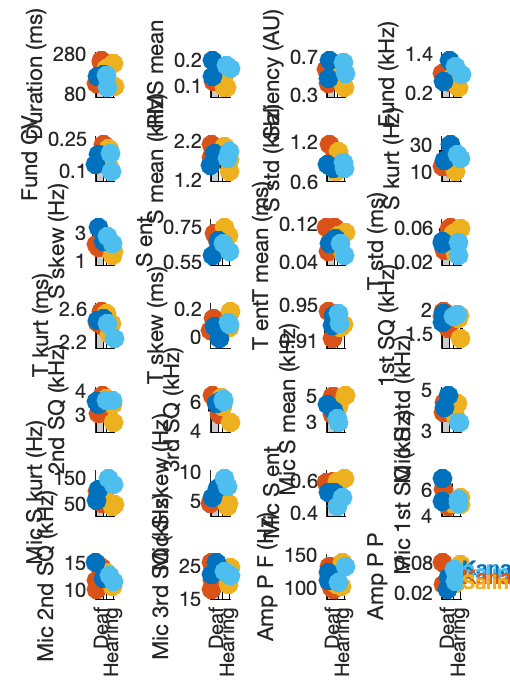

FIG1.Units = 'centimeters';
FIG1.Position(3:4) = [9 12];
FIG1.PaperSize = [9 12];

print(FIG1,fullfile(Path2Paper,'PAF_AllCalls.pdf'),'-dpdf','-fillpage')

Plot the number of calls per bat in 13 days and the amount of time they vocalized in 13 days

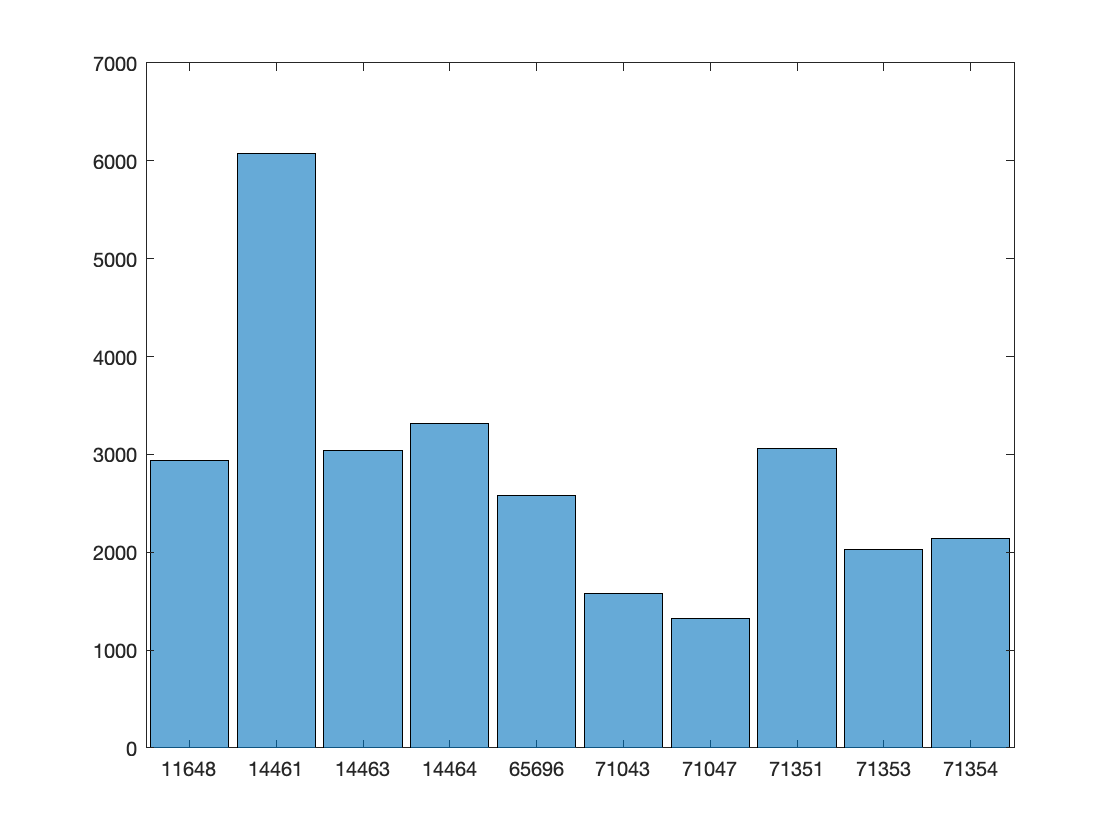

figure()
H = histogram(categorical(BatID(MicAudioGood01)));

BarData = nan(size(BatName));
CData = nan(length(BatName),3);
for bb=1:length(BatName)
    Indb = str2double(H.Categories)==BatName(bb);
    BarData(bb) = H.Values(Indb);
    CData(bb,:) = UCSexDeaf(strcmp(USexDeaf,BatSexDeaf{bb}),:);
end

Fig2=figure(2);
clf
set(gcf,'Visible','on')
subplot(1,2,1)

AcVarMedian_HD = [median(BarData(contains(BatSexDeaf, 'Kanamycin'))) median(BarData(contains(BatSexDeaf, 'Saline')))];
AcVarUQ_HD = [quantile(BarData(contains(BatSexDeaf, 'Kanamycin')),0.75) quantile(BarData(contains(BatSexDeaf, 'Saline')),0.75)];
AcVarLQ_HD = [quantile(BarData(contains(BatSexDeaf, 'Kanamycin')),0.25) quantile(BarData(contains(BatSexDeaf, 'Saline')),0.25)];

Rand = [(rand(1,length(BatSexDeaf)/2)+0.1).*0.5 (rand(1,length(BatSexDeaf)/2)*(-1)-0.1).*0.5];
Rand = Rand(randperm(length(Rand)));
XHorD = ones(size(BatSexDeaf)) + Rand;
XHorD(contains(BatSexDeaf, 'Saline')) = XHorD(contains(BatSexDeaf, 'Saline'))+2;
B=bar([1 3], AcVarMedian_HD);
hold on
errorbar([1 3],AcVarMedian_HD, AcVarMedian_HD-AcVarLQ_HD, AcVarUQ_HD-AcVarMedian_HD, 'k.', 'LineWidth',2)

B.BarWidth = 0.7;
B.FaceColor = 'flat';
B.CData(1,:) = 0.8*ones(1,3);
B.CData(2,:) = ones(1,3);
hold on
scatter(XHorD,BarData,100, Col_local, 'filled')
ylabel('# Calls')
XLim = [0 4];
set(gca, 'XLim', XLim);
MinVal = min(BarData);
MaxVal = max(BarData);
YLim = [0 MaxVal + (MaxVal-MinVal)/3];
set(gca, 'YLim', YLim)

set(gca, 'XTick', [1 3],'XTickLabel', {'Deaf' 'Hearing'})
set(gca,'Box', 'off')
% YTick= get(gca, 'YTick');
% set(gca,'YTick', [YTick(1) YTick(end)])
hold off
[p,h,stats] = ranksum(BarData(contains(BatSexDeaf, 'Kanamycin')), BarData(contains(BatSexDeaf, 'Saline')))

p = 0.3095

h = logical
   0


stats = struct with fields:
    ranksum: 22



subplot(1,2,2)

Duration_mic = DurationElmt(MicAudioGood01);
BatID_mic = BatID(MicAudioGood01);
DurationData = nan(size(BatName));
CData = nan(length(BatName),3);
for bb=1:length(BatName)
    DurationData(bb) = sum(Duration_mic(contains(BatID_mic, num2str(BatName(bb)))))./(60*10^3);
    CData(bb,:) = UCSexDeaf(strcmp(USexDeaf,BatSexDeaf{bb}),:);
end

AcVarMedian_HD = [median(DurationData(contains(BatSexDeaf, 'Kanamycin'))) median(DurationData(contains(BatSexDeaf, 'Saline')))];
AcVarLQ_HD = [quantile(DurationData(contains(BatSexDeaf, 'Kanamycin')),0.25) quantile(DurationData(contains(BatSexDeaf, 'Saline')),0.25)];
AcVarHQ_HD = [quantile(DurationData(contains(BatSexDeaf, 'Kanamycin')),0.75) quantile(DurationData(contains(BatSexDeaf, 'Saline')),0.75)];

Rand = [(rand(1,length(BatSexDeaf)/2)+0.1).*0.5 (rand(1,length(BatSexDeaf)/2)*(-1)-0.1).*0.5];
Rand = Rand(randperm(length(Rand)));
XHorD = ones(size(BatSexDeaf)) + Rand;
XHorD(contains(BatSexDeaf, 'Saline')) = XHorD(contains(BatSexDeaf, 'Saline'))+2;
B=bar([1 3], AcVarMedian_HD); 
hold on
errorbar([1 3],AcVarMedian_HD,AcVarMedian_HD-AcVarLQ_HD, AcVarHQ_HD-AcVarMedian_HD, 'k.', 'LineWidth',2)
B.BarWidth = 0.7;
B.FaceColor = 'flat';
B.CData(1,:) = 0.8*ones(1,3);
B.CData(2,:) = ones(1,3);
hold on
scatter(XHorD,DurationData,100, Col_local, 'filled')
ylabel('Time Calling (min)')
XLim = [0 4];
set(gca, 'XLim', XLim);
MinVal = min(DurationData);
MaxVal = max(DurationData);
YLim = [0 MaxVal + (MaxVal-MinVal)/3];
set(gca, 'YLim', YLim)
for ct=1:length(USexDeaf)
        text(4,YLim(2)-diff(YLim)*(2+ct)/10, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
end
set(gca, 'XTick', [1 3],'XTickLabel', {'Deaf' 'Hearing'})
set(gca,'Box', 'off')
% YTick= get(gca, 'YTick');
% set(gca,'YTick', [YTick(1) YTick(end)])
hold off

[p,h,stats] = ranksum(DurationData(contains(BatSexDeaf, 'Kanamycin')), DurationData(contains(BatSexDeaf, 'Saline')))

p = 0.3095

h = logical
   0


stats = struct with fields:
    ranksum: 22


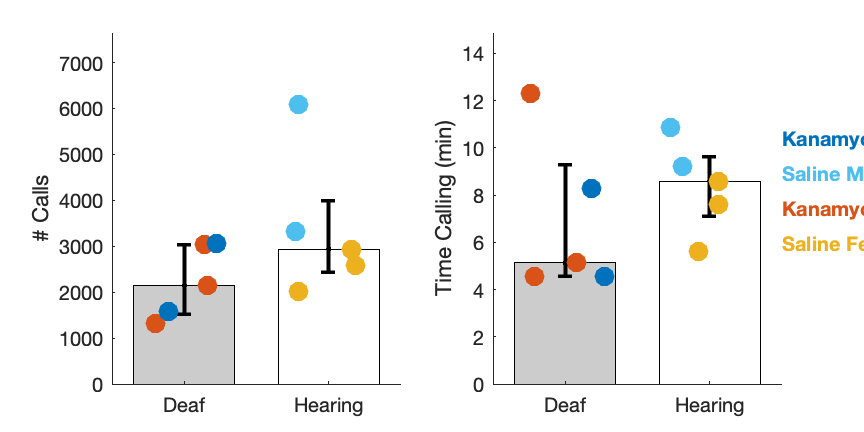


Fig2.Children(1).FontSize = 10;
Fig2.Children(2).FontSize = 10;
Fig2.Units = 'inches';
Fig2.Position(3:4) = [6 3];
Fig2.PaperSize = [6 3];
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');
print(Fig2,fullfile(Path2Paper,'SupFigure2_NumCallsTimeCalling.pdf'),'-dpdf','-fillpage')

New figure version (boxplot)

Fig3=figure(3);
clf
set(gcf,'Visible','on')
HorD = cell(size(BatSexDeaf));
for bb=1:length(BatSexDeaf)
    SP = strsplit(BatSexDeaf{bb});
    HorD{bb} = SP{1};
end
subplot(1,2,1)
boxplot([BarData(contains(BatSexDeaf, 'K'))' BarData(contains(BatSexDeaf, 'S'))'], 'Labels', {'Deaf', 'Hearing'}, 'Width',0.7);
BP = get(get(gca,'children'),'children');   % Get the handles of all the objects
Tags = get(BP, 'tag');% List the names of all the objects
BP(5).Color = [0 0 0];
BP(6).Color = [0.5 0.5 0.5];
for ll=3:14
    BP(ll).LineWidth = 2;
end
hold on
Rand = [(rand(1,length(BatSexDeaf)/2)+0.1).*0.2 (rand(1,length(BatSexDeaf)/2)*(-1)-0.1).*0.2];
Rand = Rand(randperm(length(Rand)));
XHorD = ones(size(BatSexDeaf)) + Rand;
XHorD(contains(BatSexDeaf, 'Saline')) = XHorD(contains(BatSexDeaf, 'Saline'))+1;
scatter(XHorD,BarData,100, Col_local, 'filled')
ylabel('# Calls')
XLim = [0 3];
set(gca, 'XLim', XLim);
MinVal = min(BarData);
MaxVal = max(BarData);
YLim = [0 MaxVal + (MaxVal-MinVal)/3];
set(gca, 'YLim', YLim)
set(gca,'Box', 'off')
% YTick= get(gca, 'YTick');
% set(gca,'YTick', [YTick(1) YTick(end)])
set(gca,'YTick', [0 2000 4000 6000])
hold off
[p,h,stats] = ranksum(BarData(contains(BatSexDeaf, 'Kanamycin')), BarData(contains(BatSexDeaf, 'Saline')))

p = 0.3095

h = logical
   0


stats = struct with fields:
    ranksum: 22


subplot(1,2,2)

Duration_mic = DurationElmt(MicAudioGood01);
BatID_mic = BatID(MicAudioGood01);
DurationData = nan(size(BatName));
CData = nan(length(BatName),3);
for bb=1:length(BatName)
    DurationData(bb) = sum(Duration_mic(contains(BatID_mic, num2str(BatName(bb)))))./(60*10^3);
    CData(bb,:) = UCSexDeaf(strcmp(USexDeaf,BatSexDeaf{bb}),:);
end

boxplot([DurationData(contains(BatSexDeaf, 'K'))' DurationData(contains(BatSexDeaf, 'S'))'], 'Labels', {'Deaf', 'Hearing'}, 'Width',0.7);
BP = get(get(gca,'children'),'children');   % Get the handles of all the objects
Tags = get(BP, 'tag');% List the names of all the objects
BP(5).Color = [0 0 0];
BP(6).Color = [0.5 0.5 0.5];
for ll=3:14
    BP(ll).LineWidth = 2;
end
hold on
Rand = [(rand(1,length(BatSexDeaf)/2)+0.1).*0.2 (rand(1,length(BatSexDeaf)/2)*(-1)-0.1).*0.2];
Rand = Rand(randperm(length(Rand)));
XHorD = ones(size(BatSexDeaf)) + Rand;
XHorD(contains(BatSexDeaf, 'Saline')) = XHorD(contains(BatSexDeaf, 'Saline'))+1;
scatter(XHorD,DurationData,100, Col_local, 'filled')
ylabel('Time Calling (min)')
XLim = [0 3];
set(gca, 'XLim', XLim);
MinVal = min(DurationData);
MaxVal = max(DurationData);
YLim = [0 MaxVal + (MaxVal-MinVal)/3];
set(gca, 'YLim', YLim)
set(gca,'Box', 'off')
% YTick= get(gca, 'YTick');
set(gca,'YTick', [0 5 10 15])
hold off
[p,h,stats] = ranksum(DurationData(contains(BatSexDeaf, 'Kanamycin')), DurationData(contains(BatSexDeaf, 'Saline')))

p = 0.3095

h = logical
   0


stats = struct with fields:
    ranksum: 22


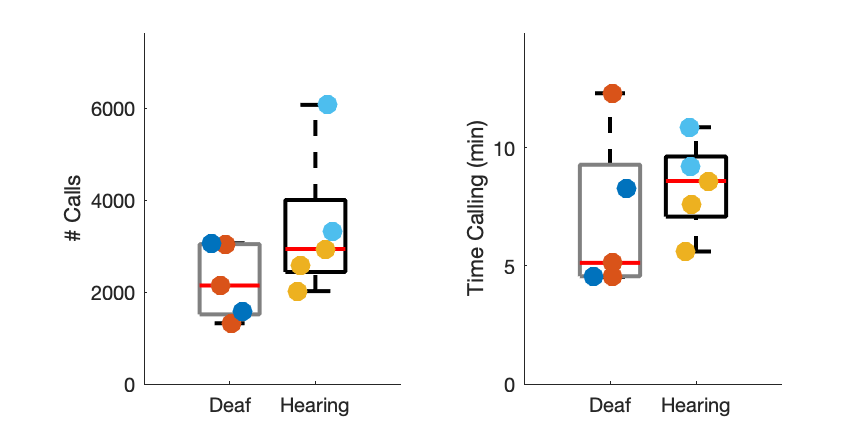

Fig3.Children(1).FontSize = 10;
Fig3.Children(2).FontSize = 10;
Fig3.Units = 'inches';
Fig3.Position(3:4) = [6 3];
Fig3.PaperSize = [6 3];
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');
print(Fig3,fullfile(Path2Paper,'SupFigure2_NumCallsTimeCallingBoxPlot.pdf'),'-dpdf','-fillpage')